1. Simulation of data with Student's t noise

n     = 50;
p     = 100;
X     = randn(n,p);
beta  = [2*ones(5,1);zeros(p-5,1)];
rng(1)
noise = random('t',4,[n,1]);
y     = X*beta+noise;

2. Lasso vs MoG-Lasso

nfold = 5;
nlambda = 50;
[B,FitInfo] = lasso(X,y,'CV',nfold,'NumLambda',nlambda);
b1 = B(:,FitInfo.Index1SE);

k = 2; % the number of Gaussian components
rho = 1;
[BETA, W, meanBIC, meanRSS, lambda] = cvmogspreg(X, y, nfold, nlambda, k, rho);
b2 = BETA(:,meanBIC==min(meanBIC)); % select the best estimate according to BIC

3. Trace plot

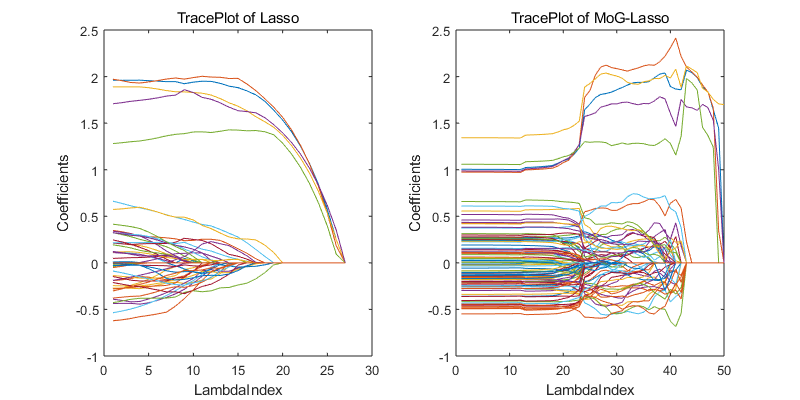

figure('Position',[300,300,800,400])
subplot(1,2,1),plot(B'),xlabel('LambdaIndex'), ylabel('Coefficients'),title('TracePlot of Lasso')
subplot(1,2,2),plot(BETA'),xlabel('LambdaIndex'), ylabel('Coefficients'),title('TracePlot of MoG-Lasso')

4. Evaluation: True positive (TP) and true negative (TN) are used for evaluate the performance. Higher the both metrices are, better the algorithm is.

true = beta~=0;
bb1 = b1~=0;
bb2 = b2~=0;
TP = [true'*bb1/5;true'*bb2/5];
TN = [(1-true)'*(1-bb1)/(p-5);(1-true)'*(1-bb2)/(p-5)];
display(table(TP,TN,'rowNames',{'Lasso','MoG-Lasso'}))

  2×2 table

                 TP      TN   
                 __    _______

    Lasso        1     0.98947
    MoG-Lasso    1           1

